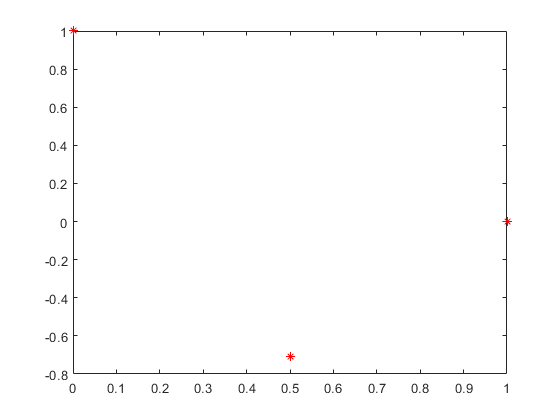

Unrecognized function or variable 'XX'.

f=@(x) cos(1.5*pi*x);
X = [0,0.5,1];
df = derivate(f);
n = 7;
for i = 1:n
    plot(X, f(X), "r*")
    hold on
    plot(XX, f(XX), "r");
    XX = linspace(min(X),max(X),100);
    S = spline(X, [df(X(1)), f(X), df(X(end))]);
    %
    plot(XX, ppval(S, XX), "black");
    
    S1 = spline(X, f(X), XX);
    plot(XX, S1, "c")
    syms t
    f1 = matlabFunction(bernstein(f, length(X)-1, t));
    plot(XX, f1(XX), "b")
    
    L = polyfit(X, f(X), length(X)-1);
    plot(XX, polyval(L, XX), "g")
    X = [X, rand(1)*2*(-1)^i]
    hold off
end